# REPELLING SLOW MANIFOLD

In this example, we use XPPLORE to show the results associated with the reconstruction of the repelling slow submanifold of a model of the silent phase of a Fitz-Hugh Nagumo system. The ODEs of the dynamical system are the following,


$$\begin{array}{l}
\dot{v} =h-\frac{v^3 -v+1}{2}-\gamma \;s\;v\\
\dot{h} =-\epsilon \;\left(2h+2\ldotp 6v\right)\\
\dot{s} =-\epsilon \;\delta \;s
\end{array}$$


The system is three-dimensional. The variables are $v$, $h$ and $s$ respectively. In the file `FHN_Sr.ode` is presented a two-point boundary-value problem (2P-BVP) implementation of this dynamical system. By using this file you are able to create the data to reconstruct a local approximation of the repelling slow manifold ${\mathcal{S}}_r^{\epsilon }$. The data that we are going to use in this example are a downsampled version of those that were created by running the different continuation steps in `FHN_Sr.ode`*. *The data are downsampled beacuse of the large dimension of the file *.dat*. We will use some costum function to create the surface to be visualized in the three-dimensional phase space. These trajectories are computed by solving a 2P-BVP. A sketch of the 2P-BVP to solve is represented in the following figure.

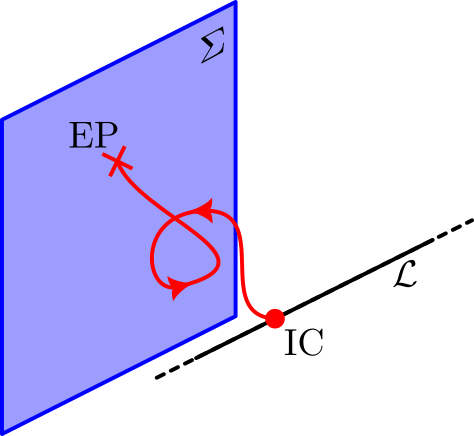

The red curve represents the solution of the 2P-BVP. Specifically, the arrows represent the flow, the dot the initial condition (IC) while the cross the end point (EP). $\mathcal{L}\;$is a line of candidate initial conditions. All the solutions of the 2P-BVP have IC over this line. All the end points of the computed solutions belongs to the plane $\Sigma$. In the following, we will create the surface obtained by concatenating all the computed special solutions started at different IC chosen over $\mathcal{L}$ and we will visualize how the so-obtained surface intersect the plane $\Sigma$.

## ENVIROMENT SET-UP

We set up the environment by cleaning the workspace and the command window of the current MATLAB session and by closing all the opened figures. Then, we proceed by importing the folders and subfolders where the main XPPLORE functions are stored.

% ENVIRONMENT
clear all; close all; clc;

% XPPLORE
addpath(genpath('../../Function_Visualization'))
addpath(genpath('../../Function_XPPAUT'))

## MODEL STRUCTURE

As usual, we read the model by using the function *Func_ReadModel.*

% MODEL
M1 = Func_ReadModel('FHN_Sr.ode');

## OPTIONs

We create a costum option structure to cut properly the visualization in the three-dimensional space. Specifically, we set the *ClippingStyle *field of the structure *opts *to *3dbox*. This allows to crop the 3D content to the set boundaries.

% OPTIONs
opts = Func_DOF(); opts.ClippingStyle = '3dbox';

## AUTORePO STRUCTURE

We load the AUTORePO structure. This contains the results of the numerical continuation. Specifically, it contains all the different trajectories. The .auto file we load is a downsampled version of the true numerical reconstruction of the repelling slow manifold of this model. We decide to downsample the reconstruction to avoid file with large dimension. Keep in mind that, if you want to load very large files XPPLORE might takes few minutes to parse the whole .auto file and allocate the required space. In this case, as it can be seen below, the AR structure contains only a single 1P-BD.

% AUTORePO
AR_Sr = Func_ReadAutoRepo(M1,'FHN_Sr.auto');

AR:
    Parsing settings ...completed!
    Parsing hot parameters ...completed!
    Parsing branches & labelled points ...completed!
    Parsing Special Solutions...completed!

    Summary:
        1P-BD - Name: BD1_sI - Main: sI


## SURFACE CREATION & PROJECTION

Now, we first retrieve all the special orbits by using the function *Func_GetTRJ*. This is the same function used in the averaging example. First, we reconstruct ${\mathcal{S}}_r^{\epsilon \;}$by concatenating all the trajectories to construct a surfcace and then we generate the curve given by the intersection between ${\mathcal{S}}_r^{\epsilon \;} \cap \Sigma$. The function used to create the surface starting from the different trajectories is the following.

The previous function requires two arguments. These are **TRJ** and **VAR**. The former is a structure containing all the different trajectories computed through numerical continuation. The latter is a cell array expecting the dynamical variables that you want to extract and save in your surface structure. We remark an important property of those solutions computed through numerical continuation. These have all the same number of time points. Therefore, they are already sampled to concatenate them toghether and generate a surface. In the following, we present the function to evaluate the projection of the surface ${\mathcal{S}}_r^{\epsilon \;}$ over the plane $\Sigma$.

All the computed solutions terminate at the plane $\Sigma$. For this reason, we only have to concatenate the end point of all the solutions to find the intersection $\Sigma \cap {\mathcal{S}}_r^{\epsilon } \;$.

% TRAJECTORIEs - Extraction
TRJ = Func_GetTRJ(M1,AR_Sr.BD1_sI);

% SLOW MANIFOLD - Surface
Sr  = Func_SlowManifold(TRJ,{'v','h','s'});

% SLOW MANIFOLD - Projection
SrP = Func_SlowManifoldProjection(TRJ,{'v','h','s'});

## VISUALIZATION - hI-lo

First of all, we visualize the results as they are presented in AUTO by visualizing along the y-axis the variable $v$ while along the x-axis the $s$-variable initial condition ($s\left(0\right)$).

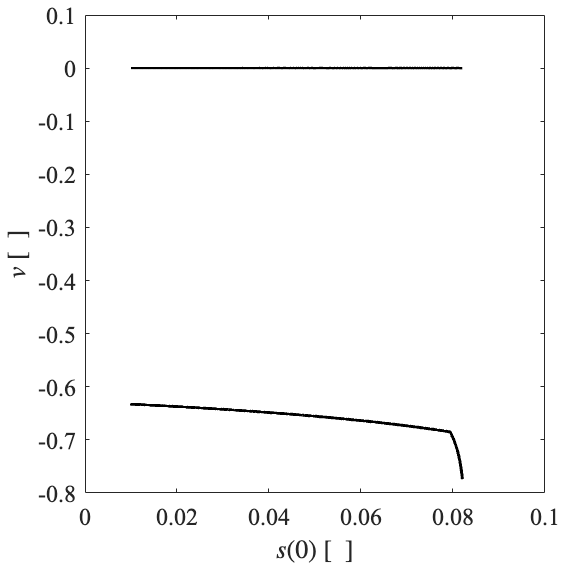

fig = figure();
Func_VisualizeDiagram(M1,AR_Sr.BD1_sI,'VAR',{'sI','v'});

xlabel('$s(0)$ [\ ]','interpreter','latex')
ylabel('$v$ [\ ]','interpreter','latex')

Func_FigStyle(fig)

## VISUALIZATION - L2

The results in AUTO sometimes are visualized by specifying along the y-axis the ${\mathcal{L}}_2$-norm as presented down below.

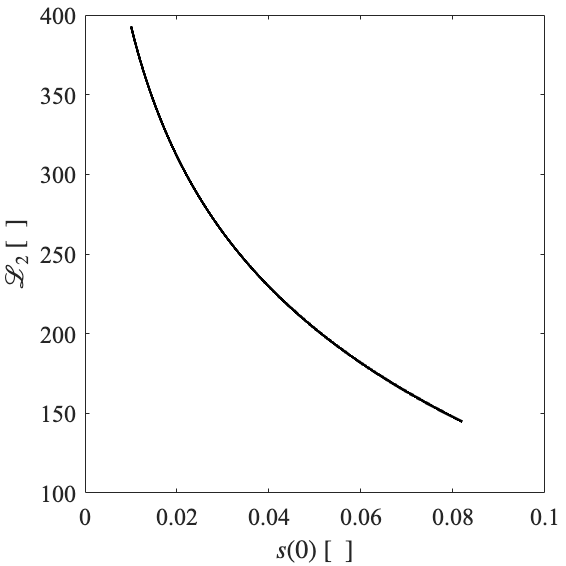

fig = figure();
Func_VisualizeDiagram(M1,AR_Sr.BD1_sI,'VAR',{'sI','L2'});

xlabel('$s(0)$ [\ ]','interpreter','latex')
ylabel('$\mathcal{L}_2$ [\ ]','interpreter','latex')

Func_FigStyle(fig)

## VISUALIZATION - 3D Surface

To visualize the repelling slow manifold, we use the built-in function *surface *of MATLAB. To apply the costum option structure, we specify by-name the parameter *opts* to the function *Func_FigStyle*. The following plot shows ${\mathcal{S}}_r^{\epsilon \;}$.

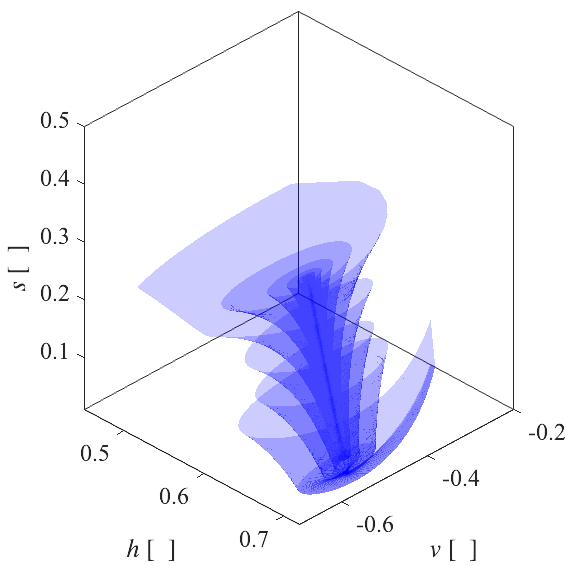

fig = figure();

hold on
surface(Sr.h,Sr.v,Sr.s,'FaceColor','b','EdgeColor','none','FaceAlpha',0.2)
hold off

xlim([0.45   0.72]); xlabel('$h$ [\ ]','interpreter','latex')
ylim([-0.7  -0.20]); ylabel('$v$ [\ ]','interpreter','latex')
zlim([0.01   0.50]); zlabel('$s$ [\ ]','interpreter','latex')

view(45,30)

Func_FigStyle(fig,'OPTIONs',opts)

## VISUALIZATION - Projection

Finally, we visualize the intersection between the surface ${\mathcal{S}}_r^{\epsilon \;}$ and $\Sigma$ by using the function *plot. *As you can see in the following plot, the curve close to its beginning shows a heavy discretization. This is related to the high-sensitivity the solution of the system presents to the initial condition by getting closer to the plane $\Sigma$ plane. We avoid in-deep explaination of these content here. 

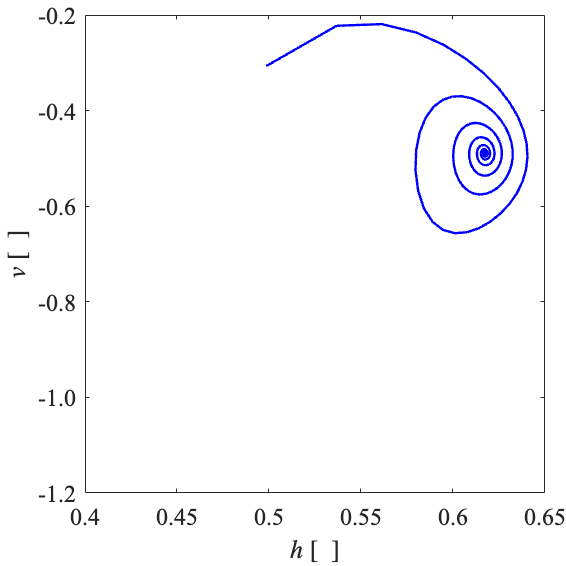

fig = figure();

hold on
plot(SrP.h,SrP.v,'Color','b','LineWidth',1.2)
hold off

xlim([0.4 0.65]), xlabel('$h$ [\ ]','interpreter','latex') 
                  xticks([0.4 0.45 0.5 0.55 0.6 0.65])
                  xticklabels({'0.4','0.45','0.5','0.55','0.6','0.65'})
ylim([-1.2 -0.2]), ylabel('$v$ [\ ]','interpreter','latex')
                   yticks([-1.2 -1.0 -0.8 -0.6 -0.4 -0.2])
                   yticklabels({'-1.2','-1.0','-0.8','-0.6','-0.4','-0.2'})

Func_FigStyle(fig)